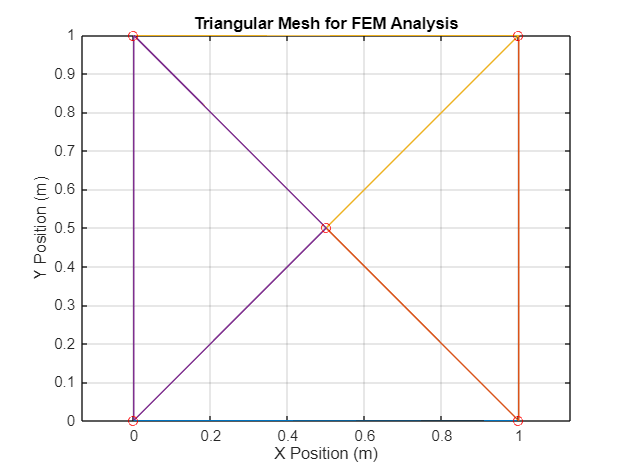

% Parameters
k = 50;               % Thermal conductivity (W/m.K)
Q = 1000;             % Heat source strength (W/m^2)
L = 1;                % Plate length (m)
T_fixed = 25;         % Boundary temperature (°C)

% Node coordinates: [x, y]
nodes = [0 0;         % Node 1
         1 0;         % Node 2
         1 1;         % Node 3
         0 1;         % Node 4
         0.5 0.5];    % Node 5 (center)

% Elements (connect corners to center node)
elements = [1 2 5;
            2 3 5;
            3 4 5;
            4 1 5];

n_nodes = size(nodes, 1);
n_elements = size(elements, 1);


%% Plot the mesh
figure;
trimesh(elements, nodes(:,1), nodes(:,2), 'LineWidth', 1);
title('Triangular Mesh for FEM Analysis');
xlabel('X Position (m)');
ylabel('Y Position (m)');
axis equal;
grid on;

%% Add annotations (optional)
hold on;
plot(nodes(:,1), nodes(:,2), 'ro', 'MarkerSize', 6); % Show nodes as red circles


% Print mesh statistics
fprintf('Mesh details:\n');

Mesh details:


fprintf('Number of nodes: %d\n', n_nodes);

Number of nodes: 5


fprintf('Number of elements: %d\n', size(elements,1));

Number of elements: 4



K = zeros(n_nodes);    % Global stiffness matrix
F = zeros(n_nodes, 1); % Global load vector

% FEM Assembly
for e = 1:n_elements
    idx = elements(e, :);
    coords = nodes(idx, :);
    x = coords(:,1); y = coords(:,2);
    
    % Area of triangle
    A = polyarea(x, y);
    
    % Compute B matrix coefficients
    b = [y(2)-y(3); y(3)-y(1); y(1)-y(2)];
    c = [x(3)-x(2); x(1)-x(3); x(2)-x(1)];
    
    % Element stiffness matrix
    ke = (k / (4*A)) * (b*b' + c*c');
    
    % Assemble global stiffness matrix
    K(idx, idx) = K(idx, idx) + ke;
end

% Apply point heat source at center node (node 5)
F(5) = F(5) + Q;

% Apply Dirichlet BC on bottom side (y=0): nodes 1 and 2
fixed_nodes = [1, 2];
free_nodes = setdiff(1:n_nodes, fixed_nodes);

% Modify system for Dirichlet BC
T = zeros(n_nodes, 1);
T(fixed_nodes) = T_fixed;

F_mod = F(free_nodes) - K(free_nodes, fixed_nodes) * T(fixed_nodes);
K_mod = K(free_nodes, free_nodes);

% Solve the system
T(free_nodes) = K_mod \ F_mod;

%% Display results
disp('Nodal Temperatures:');

Nodal Temperatures:


for i = 1:n_nodes
    fprintf('Node %d (%0.1f, %0.1f): T = %.2f°C\n', i, nodes(i,1), nodes(i,2), T(i));
end

Node 1 (0.0, 0.0): T = 25.00°C
Node 2 (1.0, 0.0): T = 25.00°C
Node 3 (1.0, 1.0): T = 35.00°C
Node 4 (0.0, 1.0): T = 35.00°C
Node 5 (0.5, 0.5): T = 35.00°C


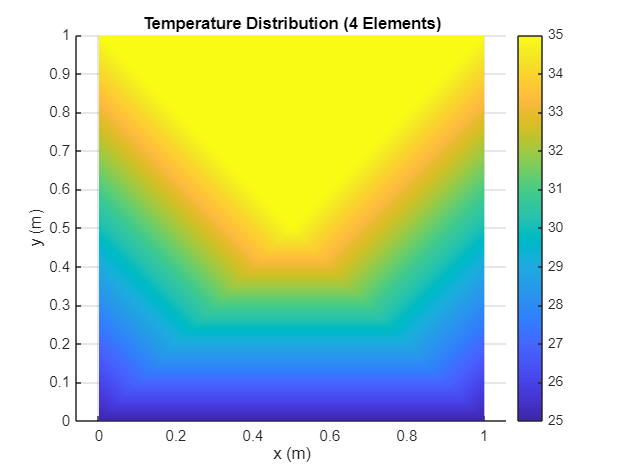


% Plotting temperature contour
figure;
trisurf(elements, nodes(:,1), nodes(:,2), T, 'FaceColor','interp');
colorbar;
title('Temperature Distribution (4 Elements)');
xlabel('x (m)'); ylabel('y (m)'); zlabel('Temperature (°C)');
view(2); axis equal; shading interp;

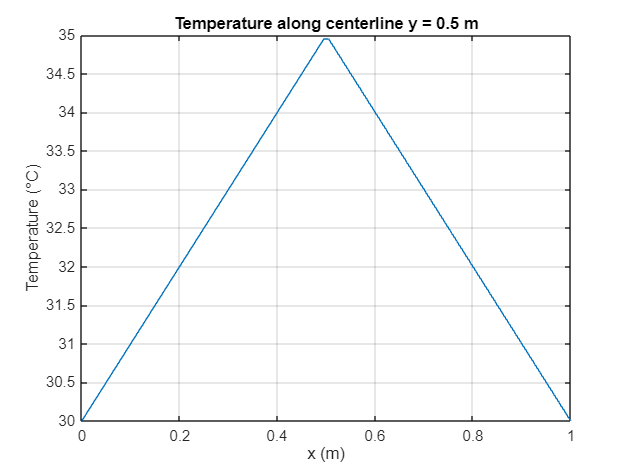


% Plot temperature along horizontal centerline y = 0.5
x_line = linspace(0, 1, 100);
yline = 0.5 * ones(size(x_line));
T_line = griddata(nodes(:,1), nodes(:,2), T, x_line, yline);

figure;
plot(x_line, T_line, '-');
title('Temperature along centerline y = 0.5 m');
xlabel('x (m)'); ylabel('Temperature (°C)');
grid on;